## Question 2 - Network Modelling

**In this question we are going to consider simple models of dense residential street networks and modifications to them that represent the implementation of low traffic neighbourhoods (LTNs).**

The code generated in this section is does work for any value of n and it executes quickly producing (hopefully) what is required in relatively uncluttered plots.

**(a) See lab sheet 02 Q1. Describe, develop, and demonstrate code which builds a Manhattan-style grid street network. The network’s junctions should constitute an n×n grid, where n is a parameter. The ‘horizontal’/‘vertical’ distance between neighbouring junctions is the same, and initially all streets should be two-way. Your implementation should use Matlab’s graph data structure.**

The following steps are required to build an n x n Manhattan-style grid street network where L is the vertical distance between neighbouring junctions and all streets are two way.

- The number of nodes in each direction and the grid "pitch" in kilometres is set. These are the input parameters.

- The figure is created.

- The input parameters are passed to the "ManhattanSquareGrid" function which generates and plots the square grid, adjusting the coordinates of nodes before outputting the graph and plot variables.

- The function is then called which initially uses numgrid generates a sparse grid using the finite differnce Laplacian where "s" specificies a square grid and the +2 allows for boundary padding. Then delsq turns this into a discrete Laplacian which is scaled by -L. This grid is then turned into a bi-directional graph with no self loops around each node and nodes names applied by ascending each column from left to right.

- This graph is then plotted and finally the coordinates of each node are set for the grid.

- Finally, the figure size is set to show clearly all nodes and node names.

Here, the code used to create this street network is put into a function as the same code is required to be run for later questions.

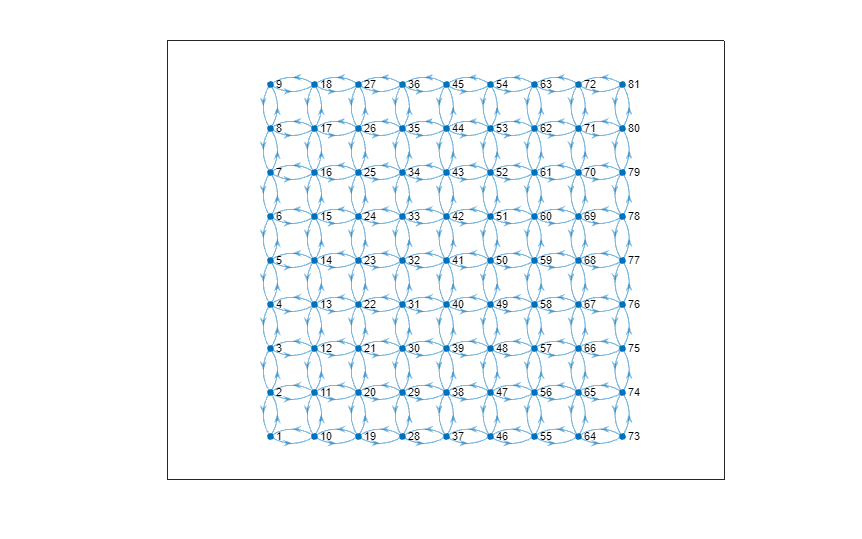

function [OutputGraph, OutputPlot] = ManhattanSquareGrid(n,L)
    % numgrid generates the finite difference Laplacian where "s" specifies
    % a square grid and n + 2 enables a border of one boundary point or padding around the grid
    % to create the desired number of visible nodes. It generates a sparse
    % grid.

    % delsq then computes the discrete Laplacian for the given sparse grid and the
    % multiplication of -L scales the grid by the grid "pitch"
    A = -L*delsq(numgrid('S',n+2));
    
    % Generating the directed graph using the matlab graphing function

    % Critically this does not create self loops around nodes and every
    % node is named from 1 to n^2 (square grid) going up the columns from
    % the bottom left and starting from the bottom row of each column
    OutputGraph = digraph(A, string(1:n^2), 'omitselfloops');

    % Plotting the directed graph
    OutputPlot = plot(OutputGraph);

    % Setting the node X and Y coordinates based upon the number of nodes
    % and grid pitch
    OutputPlot.XData = L*floor((0:n^2-1)/n);
    OutputPlot.YData = L*rem((0:n^2-1), n);
    axis equal
end

% Everything in this live script follows on from these values - these are
% the only values necessary to be changed
N = 9; % number of nodes in each direction
L = 0.1; % the grid "pitch" in kilometres

% Creating the figure
f2a = figure;

% Inputting values into grid generating function
[Q2aG, Q2ah] = ManhattanSquareGrid(N,L);

% Specifying figure size
set(gcf,'units','inches','position',[0,0,16,10])

**(b) We shall assume that the network’s streets are residential, and each street is (in the morning) the origin for a mixture of trips which terminate at the four corners of the network (perhaps before continuing subsequently to further destinations). Describe, develop, and demonstrate code which builds a new network in which the midpoint of each edge is a new node which will model the origin of the demand on that street, as indicated roughly below, for just one street.**

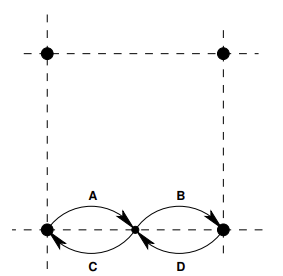

The following steps are required to build an n x n Manhattan-style grid street network where L is the vertical distance between neighbouring junctions and all streets are two way:

- Call the previous question function to create the two-way directed grid with all required nodes

- Create the plot and call the new function which creates midpoints and requires the input parameters and the directed graph just created

- Get the node names and edges node names from the inital grid and generate the new node names

- Delete all edges from the existing graph

- Add in the new nodes to the graph making sure to name them correctly using the new node names

- Set the coordinates for the "main" nodes

- Calculate the unique midpoints between each "main" node next to one another

- Setup some indexing parameters and run a for loop for all the midpoints (columns) including where new nodes are supposed to be

- A decision of where the new node is is made where if it is in a column that has already got "main" nodes. If it does, edges are created vertically between "new" and "main" nodes and coordinates set with the same X coordinate. Otherwise, edges are created horizontally between "new" and "main" nodes and coordinates set with the same Y coordinate. All coordinates are saved in a 2D array during this process.

- Finally plot the graph, set the X and Y coordinates of all nodes using the ones just calculated and resize the figure (making sure to plot node names too)

Here, the code used to create this street network is put into a function as the same code is required to be run for later questions.

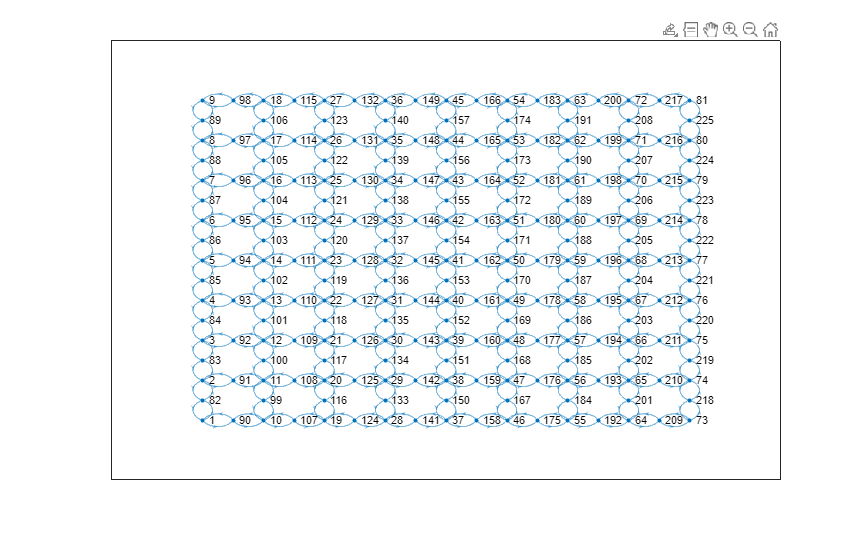

% Making previous figure not show again
f2b1 = figure('Visible','off');

% Obtaining Manhattan-style grid street network same as previous question
[Q2bG, ~] = ManhattanSquareGrid(N,L);

% Specifying figure size
set(gcf,'units','inches','position',[0,0,16,10])

function [OutputGraph, OutputPlot, OutputMainNodeNames ,OutputNewNodeNames, OutputMidpoints,...
    OutputXData, OutputYData] = ManhattanSquareGridWithMidpoints(n,L,InputGraph)

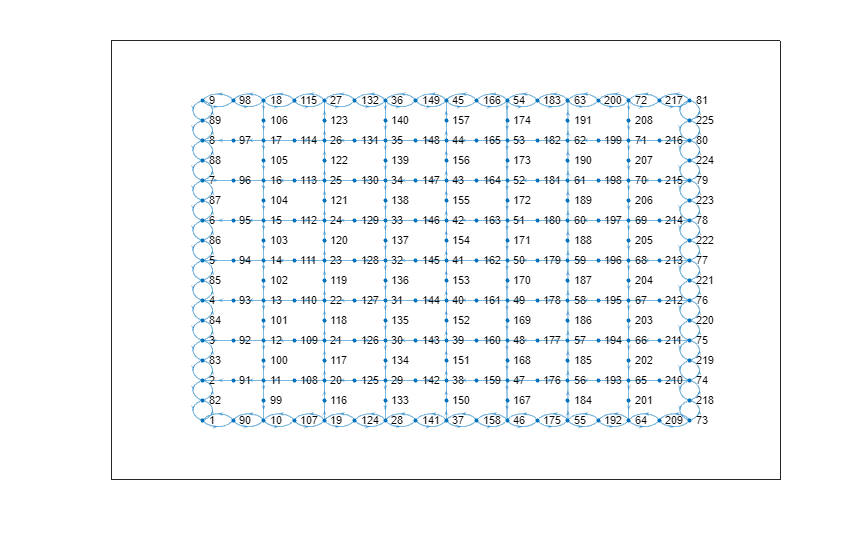

    
    % Initially setting the existing node names and new node names
    % Essential later on
    MainNodeNames = string(1:n^2);
    NewNodeNames = string(n^2+1:n^2+(n-1)*n*2);

    % Obtaining all the current edges the graph has
    EndNodes = InputGraph.Edges.EndNodes;
    
    % Deleting all edges currently in the graph
    for i=1:length(EndNodes)
        InputGraph = InputGraph.rmedge(EndNodes(i,1),EndNodes(i,2));
        InputGraph = InputGraph.rmedge(EndNodes(i,2),EndNodes(i,1));
    end
    
    % Adding in the new nodes to the graph
    for i=1:length(NewNodeNames)
        InputGraph = InputGraph.addnode(NewNodeNames(i));
    end
    
    % Setting the new coordinates for the "main" nodes in the graph taking into
    % account new nodes
    InitialXData = L*floor((0:n^2-1)/n);
    InitialYData = L*rem((0:n^2-1), n);
    
    % Obtaining the unique midpoints between the "main" nodes (a list of
    % 2n-1 size)
    Midpoints = unique((InitialXData(1:end-1) + InitialXData(2:end))/2);
    
    % Setting up array for storage of "new" node coordinates
    SubNodesCoords = zeros((n-1)*n*2,2);

    % Total index of all nodes
    index = 0;
    % Current column tracking
    Loops = 0;
    % New node index tracking
    NewNodeIndex = 0;
    
    % Looping over all columns of all nodes
    for i=1:length(Midpoints)

        % For the addition of edges to and from rows of "new" nodes
        % i.e. not "main" node columns
        if (rem(Midpoints(i),0.1) ~= 0)
            % Connecting "new" nodes to the "main" nodes to the left and
            % right by adding edges for each "new" node in the row
            for k = 1:n
                InputGraph = InputGraph.addedge(MainNodeNames((Loops-1)*n+k),NewNodeNames(NewNodeIndex+k),0.1);
                InputGraph = InputGraph.addedge(NewNodeNames(NewNodeIndex+k),MainNodeNames((Loops-1)*n+k),0.1);
                InputGraph = InputGraph.addedge(MainNodeNames((Loops)*n+k),NewNodeNames(NewNodeIndex+k),0.1);
                InputGraph = InputGraph.addedge(NewNodeNames(NewNodeIndex+k),MainNodeNames((Loops)*n+k),0.1);
            end
            % Adding the number of nodes that have been added by the
            % previous loop
            NewNodeIndex = NewNodeIndex + n;
            
            % Saving the coordinates of the new nodes for application later
            % on - loop cycles through all rows the "main" nodes are on
            for j=1:length(Midpoints)
                if (rem(Midpoints(j),0.1) == 0)
                    index = index + 1;
                    SubNodesCoords(index,1) = Midpoints(i);
                    SubNodesCoords(index,2) = Midpoints(j);
                end
            end
        % For the addition of edges to and from columns of "new" nodes -
        % i.e. "main" node columns
        else
            % Catching the "new" nodes at the top and bottom of each column
            InputGraph = InputGraph.addedge(MainNodeNames(Loops*n+1),NewNodeNames(NewNodeIndex+1),0.1);
            InputGraph = InputGraph.addedge(NewNodeNames(NewNodeIndex+1),MainNodeNames(Loops*n+1),0.1);
            InputGraph = InputGraph.addedge(MainNodeNames(Loops*n+n),NewNodeNames(NewNodeIndex+(n-1)),0.1);
            InputGraph = InputGraph.addedge(NewNodeNames(NewNodeIndex+(n-1)),MainNodeNames(Loops*n+n),0.1);
            % Connecting "new" nodes to the "main" nodes by the top and
            % bottom by adding edges for each "new" node in the column
            for k = 2:(n-1)
                InputGraph = InputGraph.addedge(MainNodeNames(Loops*n+k),NewNodeNames(NewNodeIndex+k),0.1);
                InputGraph = InputGraph.addedge(NewNodeNames(NewNodeIndex+k),MainNodeNames(Loops*n+k),0.1);
                InputGraph = InputGraph.addedge(MainNodeNames(Loops*n+k),NewNodeNames(NewNodeIndex+k-1),0.1);
                InputGraph = InputGraph.addedge(NewNodeNames(NewNodeIndex+k-1),MainNodeNames(Loops*n+k),0.1);
            end

            % Column index
            Loops = Loops + 1;
            % Adding the number of nodes that have been added by the
            % previous loop
            NewNodeIndex = NewNodeIndex + (n-1);
            % Saving the coordinates of the new nodes for application later
            % on - loop cycles through all rows the "main" nodes are NOT on
            for j=1:length(Midpoints)
                if (rem(Midpoints(j),0.1) ~= 0)
                    index = index + 1;
                    SubNodesCoords(index,1) = Midpoints(i);
                    SubNodesCoords(index,2) = Midpoints(j);
                end
            end
        end
    end
    
    % Saving the graph, node names and midpoints for output
    OutputGraph = InputGraph;
    OutputMainNodeNames = MainNodeNames;
    OutputNewNodeNames = NewNodeNames;
    OutputMidpoints = Midpoints;

    % Setting the output node x and y coordinates for output
    NewXData = [InitialXData SubNodesCoords(:,1)'];
    NewYData = [InitialYData SubNodesCoords(:,2)'];

    OutputXData = NewXData;
    OutputYData = NewYData;

    % Plotting the graph and labelling nodes
    OutputPlot = plot(InputGraph,'NodeLabel', InputGraph.Nodes.Name);
    
    % Setting the coordinates of the nodes on the plot
    OutputPlot.XData = NewXData;
    OutputPlot.YData = NewYData;
end


% creating the figure
f2b2 = figure;

ans = 1


% Calling the function making sure to specify the output variables if
% necessary
[Q2bGWithMidpoints, Q2bhWithMidpoints, Q2bWithMidpointsMainNodeNames ,Q2bWithMidpointsNewNodeNames, ...
    Q2bWithMidpointsMidpoints, Q2bWithMidpointsXData, Q2bWithMidpointsYData] = ...
    ManhattanSquareGridWithMidpoints(N,L,Q2bG);

% Specifying figure size
set(gcf,'units','inches','position',[0,0,16,10])

**(c) Investigate designs for LTNs. You might want to try and make some streets oneway (for example, by closing links A and B in the above figure) or blocking off the ends of streets at some junctions (for example, by closing links B and D in the above figure). Good designs will try to maximise the number of blocked-off streets (which are thus free of through traffic) and make large numbers of the remaining through streets one-way, in order to simplify the traffic flow. However, each street’s residents must retain a viable route to each corner of the network (and be able to return to their homes in the evening). Describe, develop, and demonstrate Matlab code which implements and displays your modified networks and which verifies the required connectivity. Note: highest marks will be reserved for solutions that work for any value of n, but if you find that too hard, setting n to a fixed value larger or equal to 10 is fine.**

In this question, four designs of LTNs are considered using varying degrees of one-way and blocked streets at junctions. Once again, these are all scalable for any value of n. The four designs of LTN are:

**LTN Design 1 - Making each row and column become one way, alternating in direction and maintaining the outer two-way streets.**

Steps:

- Iterating through all columns, using an if statement to select "new" and "main" node columns

- In "new" node columns, all "inner" rows have one edge on the left and one edge on the right deleted horizontally before this is alternated for each row

- In "main" node columns, the top and bottom nodes have one top and bottom edge deleted vertically and then the central nodes all have the same directed edge deleted to create a one-way street

Positives: Good implementation of alternating direction one-way streets in the vertical column direction. Relatively simple to implement with few "if" statements

Negatives: Doesn't implement one-way streets in the horizontal direction properly

**LTN Design 2 - Similar to LTN Design 1 but maintaining a "cross" of two-way streets at the central nodes.**

Steps:

- Iterating through all columns, using an if statement to select "new" and "main" node columns but misses out the central column

- In "new" node columns, all "inner" rows have one edge on the left and one edge on the right deleted horizontally before this is alternated for each row but misses out the central row

- In "main" node columns, the top and bottom nodes have one top and bottom edge deleted vertically and then the central nodes all have the same directed edge deleted to create a one-way street

Positives: Once again good implementation of vertical one-way streets and helps traffic flow by keeping the two-way streets

Negatives: Doesn't implement one-way streets in the horizontal direction properly and probably doesn't add to much to ease traffic. Uses "if" statements to avoid central columns which are inefficient.

**LTN Design 3 - Similar to LTN Design 1 but each row only contains one two way-street that is blocked on the left side **

Steps: 

- Iterating through all columns, using an if statement to select "new" and "main" node columns

- In "new" node columns, all "inner" rows have both edges on the left deleted horizontally before this is alternated for each row 

- In "main" node columns, the top and bottom nodes have one top and bottom edge deleted vertically and then the central nodes all have the same directed edge deleted to create a one-way street

Positives: Good implementation of one-way streets and useful road blocks that don't put too much pressure on most roads. A good implementation.

Negatives: Best implementation, only criticism is the most right "central" nodes are connected to the outer two way streets which could apply a lot of pressure there

**LTN Design 4 - A combination of all i.e. similar to LTN Design 1 but each row only contains one two way-street that is blocked on the left but maintaining a "cross" at the central nodes of two-way streets. **

Steps:

- Combination of all of the above

- Iterating through all columns, using an if statement to select "new" and "main" node columns but misses out the central column

- In "new" node columns, all "inner" rows have both edges on the left deleted horizontally before this is alternated for each row but misses out the central row

- In "main" node columns, the top and bottom nodes have one top and bottom edge deleted vertically and then the central nodes all have the same directed edge deleted to create a one-way street

Positives: Good implementation of one-way streets and useful road blocks that don't put too much pressure on most roads. Central two-way streets does aid traffic flow

Negatives: Once again, most right "central" nodes are connected to the outer two way streets which could apply a lot of pressure and uses if" statements to avoid central columns which are inefficient.

It is validated that each resident still has a viable route to each corner by the destination being randomly assigned and the connectivity calculated. A connectivity of 1 suggests all nodes can reach all other nodes and therefore their destination. 

However, it is appreciated that although these designs may be good, they are not the best available with further road closures and one-way streets possible in all LTN designs.

## LTN design 1 - Maintaining outside loop + one way

ans = 1.9956

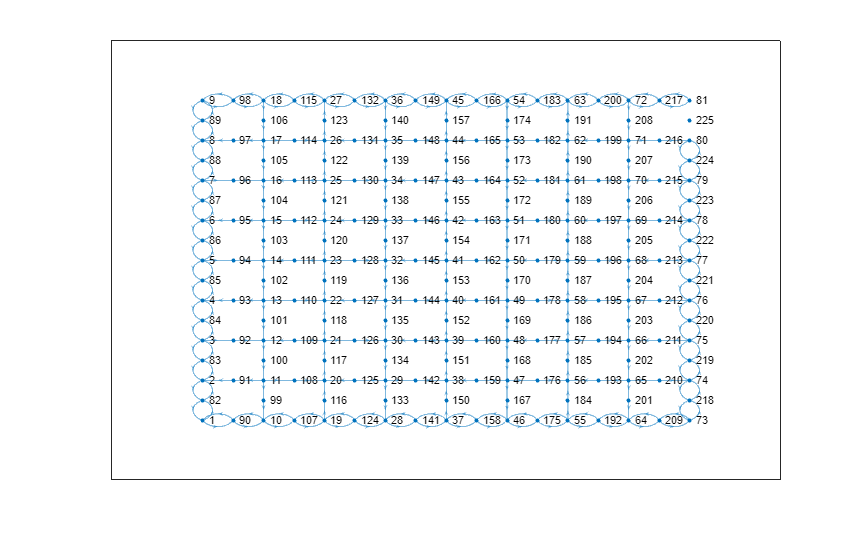

% LTN design 1 - Maintaining outside loop + one way

% Setting up initial Manhattan-style square grid
f2c1a = figure('Visible','off');
[Q2cGLTN1, ~] = ManhattanSquareGrid(N,L);

% Setting up the "new" grid which includes the "new" midpoint nodes
f2c1b = figure('Visible','off');

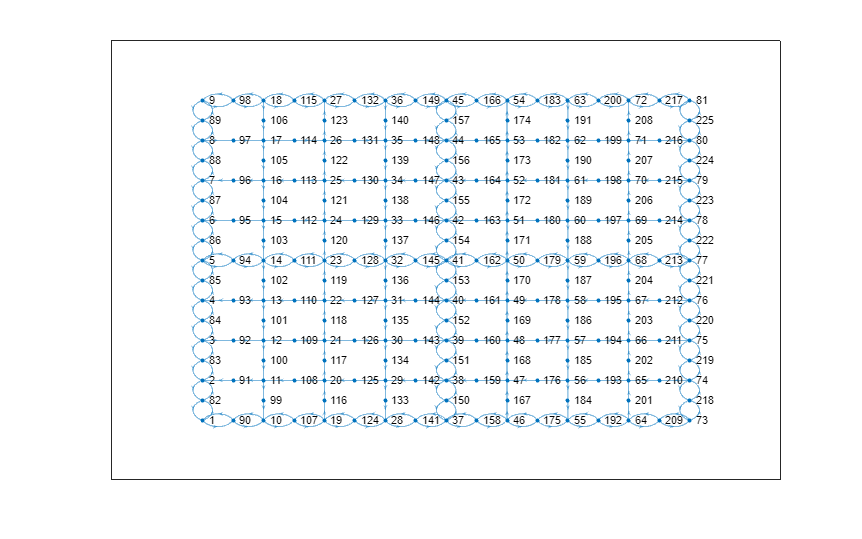

[Q2cGLTN1, ~, Q2cGLTN1MainNodeNames, Q2cGLTN1NewNodeNames, Q2cGLTN1Midpoints, Q2cGLTN1XData, Q2cGLTN1YData] = ...
    ManhattanSquareGridWithMidpoints(N,L,Q2cGLTN1);


Loops = 1; % this cycles through each column
NewNodeIndex = (N-1); % New nodes i.e. 101 to 280 fo n = 10
XAlt = 1; % Alternating rows index
YAlt = 1; % Alternating columns index


for i=1:length(Q2cGLTN1Midpoints)
    % "New" node columns
    if (rem(Q2cGLTN1Midpoints(i),0.1) ~= 0)
        % Iterating through th rows - missing out the "outer" rows
        for k = 2:(N-1)
            if XAlt == 1
                % Deleting left and right bits of columns horizontally
                Q2cGLTN1 = Q2cGLTN1.rmedge(Q2cGLTN1MainNodeNames((Loops-1)*N+k),Q2cGLTN1NewNodeNames(NewNodeIndex+k));
                Q2cGLTN1 = Q2cGLTN1.rmedge(Q2cGLTN1NewNodeNames(NewNodeIndex+k),Q2cGLTN1MainNodeNames((Loops)*N+k));
                % Making sure to alternate
                XAlt = 2;
            elseif XAlt == 2
                % Deleting left and right bits of columns horizontally
                Q2cGLTN1 = Q2cGLTN1.rmedge(Q2cGLTN1NewNodeNames(NewNodeIndex+k),Q2cGLTN1MainNodeNames((Loops-1)*N+k));
                Q2cGLTN1 = Q2cGLTN1.rmedge(Q2cGLTN1MainNodeNames((Loops)*N+k),Q2cGLTN1NewNodeNames(NewNodeIndex+k));
                % Making sure to alternate
                XAlt = 1;
            end
        end
        % Adding the number of nodes that have been added by the
        % previous loop
        NewNodeIndex = NewNodeIndex + N;
    % "Old" node columns - missing out the "outer" columns
    elseif (Q2cGLTN1Midpoints(i)> Q2cGLTN1Midpoints(1) && Q2cGLTN1Midpoints(i) < Q2cGLTN1Midpoints(end-1))
        if YAlt == 1
            % Deleting top and bottom bits of columns vertically
            Q2cGLTN1 = Q2cGLTN1.rmedge(Q2cGLTN1MainNodeNames(Loops*N+1),Q2cGLTN1NewNodeNames(NewNodeIndex+1));
            Q2cGLTN1 = Q2cGLTN1.rmedge(Q2cGLTN1NewNodeNames(NewNodeIndex+(N-1)),Q2cGLTN1MainNodeNames(Loops*N+N));
            % Iterating through the "inner" rows
            for k = 2:(N-1)
                % Deleting central bits of columns vertically
                Q2cGLTN1 = Q2cGLTN1.rmedge(Q2cGLTN1MainNodeNames(Loops*N+k),Q2cGLTN1NewNodeNames(NewNodeIndex+k));
                Q2cGLTN1 = Q2cGLTN1.rmedge(Q2cGLTN1NewNodeNames(NewNodeIndex+k-1),Q2cGLTN1MainNodeNames(Loops*N+k));
            end
            % Making sure to alternate
            YAlt = 2;
        elseif YAlt == 2
            % Deleting top and bottom bits of columns vertically
            Q2cGLTN1 = Q2cGLTN1.rmedge(Q2cGLTN1NewNodeNames(NewNodeIndex+1),Q2cGLTN1MainNodeNames(Loops*N+1));
            Q2cGLTN1 = Q2cGLTN1.rmedge(Q2cGLTN1MainNodeNames(Loops*N+N),Q2cGLTN1NewNodeNames(NewNodeIndex+(N-1)));
            % Iterating through the "inner" rows
            for k = 2:(N-1)
                % Deleting central bits of columns vertically
                Q2cGLTN1 = Q2cGLTN1.rmedge(Q2cGLTN1NewNodeNames(NewNodeIndex+k),Q2cGLTN1MainNodeNames(Loops*N+k));
                Q2cGLTN1 = Q2cGLTN1.rmedge(Q2cGLTN1MainNodeNames(Loops*N+k),Q2cGLTN1NewNodeNames(NewNodeIndex+k-1));
            end
            % Making sure to alternate
            YAlt = 1;
        end

        % Column index
        Loops = Loops + 1;
        % Adding the number of nodes that have been added by the
        % previous loop
        NewNodeIndex = NewNodeIndex + (N-1);
    end
end

% Plotting updated graph
f2c1c = figure;
Q2hLTN1 = plot(Q2cGLTN1,'NodeLabel',Q2cGLTN1.Nodes.Name);

% Specifying figure size
set(gcf,'units','inches','position',[0,0,16,10])

% Specifying graph node coordinates
hold on;
Q2hLTN1.XData = Q2cGLTN1XData;
Q2hLTN1.YData = Q2cGLTN1YData;
hold off;

% Verifying required connectivity -> should be 1
sum(conncomp(Q2cGLTN1,'Type','strong'))/(length(Q2cGLTN1XData))
% Disconnecting the final "new" node in the top right corner of the plot as
% a sanity check
Q2cGLTN1 = Q2cGLTN1.rmedge(Q2cGLTN1NewNodeNames(end),Q2cGLTN1MainNodeNames(end));
Q2cGLTN1 = Q2cGLTN1.rmedge(Q2cGLTN1MainNodeNames(end),Q2cGLTN1NewNodeNames(end));
Q2cGLTN1 = Q2cGLTN1.rmedge(Q2cGLTN1NewNodeNames(end),Q2cGLTN1MainNodeNames(end-1));
Q2cGLTN1 = Q2cGLTN1.rmedge(Q2cGLTN1MainNodeNames(end-1),Q2cGLTN1NewNodeNames(end));

% Now all nodes will have varying values due to their independent
% connectivity
sum(conncomp(Q2cGLTN1,'Type','strong'))/(length(Q2cGLTN1XData))
% Plot showing the disconnected node
f2c1d = figure;
Q2hLTN1 = plot(Q2cGLTN1,'NodeLabel',Q2cGLTN1.Nodes.Name);

set(gcf,'units','inches','position',[0,0,16,10])
hold on;
Q2hLTN1.XData = Q2cGLTN1XData;

ans = 1

Q2hLTN1.YData = Q2cGLTN1YData;
hold off;

## LTN design 2 Maintaining outside loop + one way + cross


% LTN design 2 Maintaining outside loop + one way + cross

% Setting up initial Manhattan-style square grid
f2c2a = figure('Visible','off');
[Q2cGLTN2, ~] = ManhattanSquareGrid(N,L);

% Setting up the "new" grid which includes the "new" midpoint nodes

ans = 1.9956

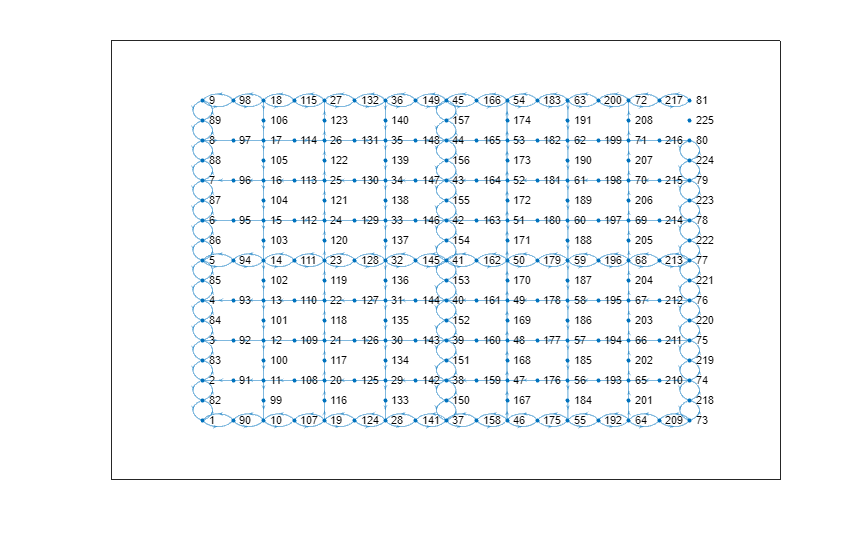

f2c2b = figure('Visible','off');
[Q2cGLTN2, ~, Q2cGLTN2MainNodeNames, Q2cGLTN2NewNodeNames, Q2cGLTN2Midpoints, Q2cGLTN2XData, Q2cGLTN2YData] = ...
    ManhattanSquareGridWithMidpoints(N,L,Q2cGLTN2);

Loops = 1; % this cycles through each column
NewNodeIndex = (N-1); % New nodes i.e. 101 to 280
XAlt = 1; % Alternating rows
YAlt = 1; % Alternating columns

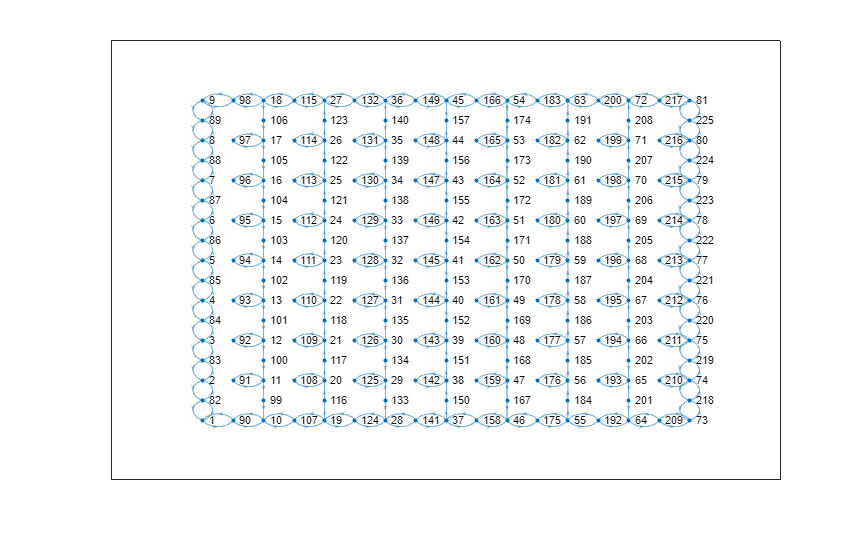


% Skipping out the middle row
Rows = 2:(N-1);
Rows(round(end/2)) = [];

for i=1:length(Q2cGLTN2Midpoints)
    % Skipping out the middle column
    if (rem(N,2) == 0 && Q2cGLTN2Midpoints(i) == Q2cGLTN2Midpoints(round(end/2)))
        NewNodeIndex = NewNodeIndex + N;
    elseif (rem(N,2) ~= 0 && Q2cGLTN2Midpoints(i) == Q2cGLTN2Midpoints(round(end/2)))
        NewNodeIndex = NewNodeIndex + N-1;
        Loops = Loops + 1;
    % "New" node columns
    elseif (rem(Q2cGLTN2Midpoints(i),0.1) ~= 0)
        % Iterating through th rows - missing out the "outer" and middle rows
        for k = Rows
            if XAlt == 1
                % Deleting left and right bits of columns horizontally
                Q2cGLTN2 = Q2cGLTN2.rmedge(Q2cGLTN2MainNodeNames((Loops-1)*N+k),Q2cGLTN2NewNodeNames(NewNodeIndex+k));
                Q2cGLTN2 = Q2cGLTN2.rmedge(Q2cGLTN2NewNodeNames(NewNodeIndex+k),Q2cGLTN2MainNodeNames((Loops)*N+k));
                % Making sure to alternate
                XAlt = 2;
            elseif XAlt == 2
                % Deleting left and right bits of columns horizontally
                Q2cGLTN2 = Q2cGLTN2.rmedge(Q2cGLTN2NewNodeNames(NewNodeIndex+k),Q2cGLTN2MainNodeNames((Loops-1)*N+k));
                Q2cGLTN2 = Q2cGLTN2.rmedge(Q2cGLTN2MainNodeNames((Loops)*N+k),Q2cGLTN2NewNodeNames(NewNodeIndex+k));
                % Making sure to alternate
                XAlt = 1;
            end
        end
        % Adding the number of nodes that have been added by the
        % previous loop
        NewNodeIndex = NewNodeIndex + N;
    % "Old" node columns - missing out the "outer" columns
    elseif (Q2cGLTN2Midpoints(i)> Q2cGLTN2Midpoints(1) && Q2cGLTN2Midpoints(i) < Q2cGLTN2Midpoints(end-1))
        if YAlt == 1
            % Deleting top and bottom bits of columns vertically
            Q2cGLTN2 = Q2cGLTN2.rmedge(Q2cGLTN2MainNodeNames(Loops*N+1),Q2cGLTN2NewNodeNames(NewNodeIndex+1));
            Q2cGLTN2 = Q2cGLTN2.rmedge(Q2cGLTN2NewNodeNames(NewNodeIndex+(N-1)),Q2cGLTN2MainNodeNames(Loops*N+N));
            % Iterating through the "inner" rows
            for k = 2:(N-1)
                % Deleting central bits of columns vertically
                Q2cGLTN2 = Q2cGLTN2.rmedge(Q2cGLTN2MainNodeNames(Loops*N+k),Q2cGLTN2NewNodeNames(NewNodeIndex+k));
                Q2cGLTN2 = Q2cGLTN2.rmedge(Q2cGLTN2NewNodeNames(NewNodeIndex+k-1),Q2cGLTN2MainNodeNames(Loops*N+k));
            end
            % Making sure to alternate
            YAlt = 2;
        elseif YAlt == 2
            % Deleting top and bottom bits of columns vertically
            Q2cGLTN2 = Q2cGLTN2.rmedge(Q2cGLTN2NewNodeNames(NewNodeIndex+1),Q2cGLTN2MainNodeNames(Loops*N+1));
            Q2cGLTN2 = Q2cGLTN2.rmedge(Q2cGLTN2MainNodeNames(Loops*N+N),Q2cGLTN2NewNodeNames(NewNodeIndex+(N-1)));
            % Iterating through the "inner" rows
            for k = 2:(N-1)
                % Deleting central bits of columns vertically
                Q2cGLTN2 = Q2cGLTN2.rmedge(Q2cGLTN2NewNodeNames(NewNodeIndex+k),Q2cGLTN2MainNodeNames(Loops*N+k));
                Q2cGLTN2 = Q2cGLTN2.rmedge(Q2cGLTN2MainNodeNames(Loops*N+k),Q2cGLTN2NewNodeNames(NewNodeIndex+k-1));
            end
            % Making sure to alternate
            YAlt = 1;
        end
        % Column index
        Loops = Loops + 1;
        % Adding the number of nodes that have been added by the
        % previous loop
        NewNodeIndex = NewNodeIndex + (N-1);
    end
end
% Plotting updated graph
f2c2c = figure;
Q2hLTN2 = plot(Q2cGLTN2,'NodeLabel',Q2cGLTN2.Nodes.Name);

% Specifying figure size
set(gcf,'units','inches','position',[0,0,16,10])

% Specifying graph node coordinates
hold on;
Q2hLTN2.XData = Q2cGLTN2XData;
Q2hLTN2.YData = Q2cGLTN2YData;
hold off;

% Verifying required connectivity -> should be 1
sum(conncomp(Q2cGLTN2,'Type','strong'))/(length(Q2cGLTN2XData))
% Disconnecting the final "new" node in the top right corner of the plot as
% a sanity check
Q2cGLTN2 = Q2cGLTN2.rmedge(Q2cGLTN2NewNodeNames(end),Q2cGLTN2MainNodeNames(end));

Q2cGLTN2 = Q2cGLTN2.rmedge(Q2cGLTN2MainNodeNames(end),Q2cGLTN2NewNodeNames(end));
Q2cGLTN2 = Q2cGLTN2.rmedge(Q2cGLTN2NewNodeNames(end),Q2cGLTN2MainNodeNames(end-1));
Q2cGLTN2 = Q2cGLTN2.rmedge(Q2cGLTN2MainNodeNames(end-1),Q2cGLTN2NewNodeNames(end));

ans = 1


% Now all nodes will have varying values due to their independent
% connectivity
sum(conncomp(Q2cGLTN2,'Type','strong'))/(length(Q2cGLTN2XData))
% Plot showing the disconnected node
f2c2d = figure;
Q2hLTN2 = plot(Q2cGLTN2,'NodeLabel',Q2cGLTN2.Nodes.Name);
set(gcf,'units','inches','position',[0,0,16,10])
hold on;
Q2hLTN2.XData = Q2cGLTN2XData;

ans = 1.9956

Q2hLTN2.YData = Q2cGLTN2YData;
hold off;

## LTN design 3 - Maintaining outside loop + one way + blocking off

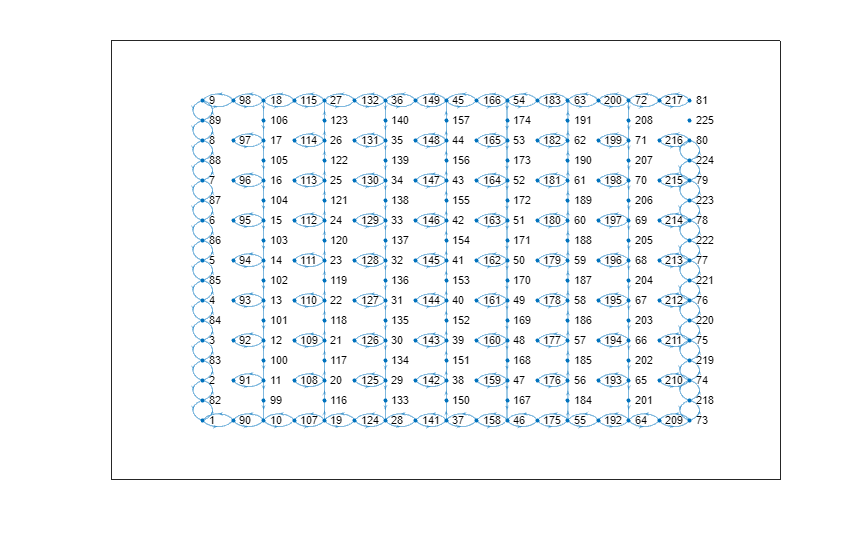


% LTN design 3 - Maintaining outside loop + one way + blocking off

% Setting up initial Manhattan-style square grid
f2c3a = figure('Visible','off');
[Q2cGLTN3, ~] = ManhattanSquareGrid(N,L);

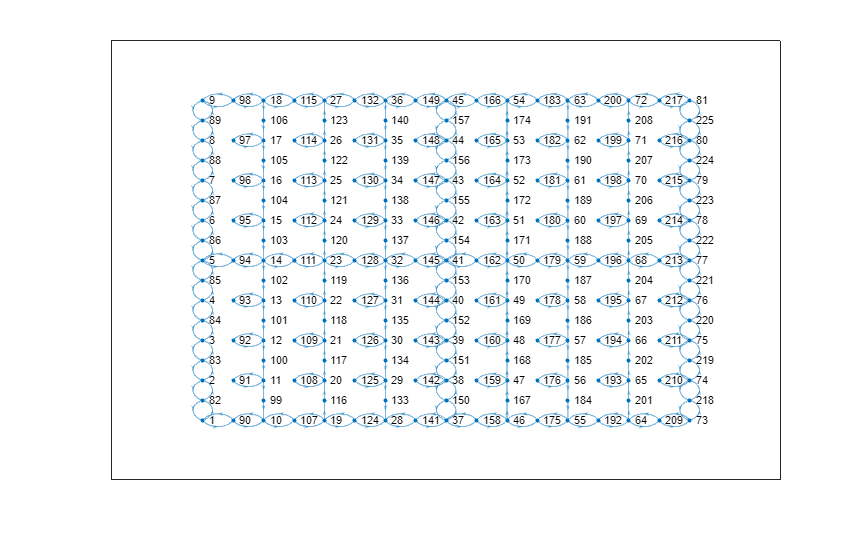


% Setting up the "new" grid which includes the "new" midpoint nodes
f2c3b = figure('Visible','off');
[Q2cGLTN3, ~, Q2cGLTN3MainNodeNames, Q2cGLTN3NewNodeNames, Q2cGLTN3Midpoints, Q2cGLTN3XData, Q2cGLTN3YData] = ...
    ManhattanSquareGridWithMidpoints(N,L,Q2cGLTN3);

Loops = 1; % this cycles through each column
NewNodeIndex = (N-1); % New nodes i.e. 101 to 280
XAlt = 1; % Alternating rows
YAlt = 1; % Alternating columns


for i=1:length(Q2cGLTN1Midpoints)
    % "New" node columns
    if (rem(Q2cGLTN1Midpoints(i),0.1) ~= 0)
        % Iterating through th rows - missing out the "outer" and middle rows
        for k = 2:(N-1)
            if XAlt == 1
                % Deleting left and right bits of columns horizontally
                Q2cGLTN3 = Q2cGLTN3.rmedge(Q2cGLTN3MainNodeNames((Loops-1)*N+k),Q2cGLTN3NewNodeNames(NewNodeIndex+k));
                Q2cGLTN3 = Q2cGLTN3.rmedge(Q2cGLTN3NewNodeNames(NewNodeIndex+k),Q2cGLTN3MainNodeNames((Loops-1)*N+k));
                % Making sure to alternate
                XAlt = 2;
            elseif XAlt == 2
                % Deleting left and right bits of columns horizontally
                Q2cGLTN3 = Q2cGLTN3.rmedge(Q2cGLTN3NewNodeNames(NewNodeIndex+k),Q2cGLTN3MainNodeNames((Loops-1)*N+k));
                Q2cGLTN3 = Q2cGLTN3.rmedge(Q2cGLTN3MainNodeNames((Loops-1)*N+k),Q2cGLTN3NewNodeNames(NewNodeIndex+k));
                % Making sure to alternate
                XAlt = 1;
            end
        end
        % Adding the number of nodes that have been added by the
        % previous loop
        NewNodeIndex = NewNodeIndex + N;
    % "Old" node columns - missing out the "outer" columns
    elseif (Q2cGLTN3Midpoints(i)> Q2cGLTN3Midpoints(1) && Q2cGLTN3Midpoints(i) < Q2cGLTN3Midpoints(end-1))
        if YAlt == 1
            % Deleting top and bottom bits of columns vertically
            Q2cGLTN3 = Q2cGLTN3.rmedge(Q2cGLTN3MainNodeNames(Loops*N+1),Q2cGLTN3NewNodeNames(NewNodeIndex+1));
            Q2cGLTN3 = Q2cGLTN3.rmedge(Q2cGLTN3NewNodeNames(NewNodeIndex+(N-1)),Q2cGLTN3MainNodeNames(Loops*N+N));
            for k = 2:(N-1)
                % % Deleting central bits of columns vertically
                Q2cGLTN3 = Q2cGLTN3.rmedge(Q2cGLTN3MainNodeNames(Loops*N+k),Q2cGLTN3NewNodeNames(NewNodeIndex+k));
                Q2cGLTN3 = Q2cGLTN3.rmedge(Q2cGLTN3NewNodeNames(NewNodeIndex+k-1),Q2cGLTN3MainNodeNames(Loops*N+k));
            end
            % Making sure to alternate
            YAlt = 2;
        elseif YAlt == 2
            % Deleting top and bottom bits of columns vertically
            Q2cGLTN3 = Q2cGLTN3.rmedge(Q2cGLTN3NewNodeNames(NewNodeIndex+1),Q2cGLTN3MainNodeNames(Loops*N+1));
            Q2cGLTN3 = Q2cGLTN3.rmedge(Q2cGLTN3MainNodeNames(Loops*N+N),Q2cGLTN3NewNodeNames(NewNodeIndex+(N-1)));
            for k = 2:(N-1)
                % Deleting central bits of columns vertically
                Q2cGLTN3 = Q2cGLTN3.rmedge(Q2cGLTN3NewNodeNames(NewNodeIndex+k),Q2cGLTN3MainNodeNames(Loops*N+k));
                Q2cGLTN3 = Q2cGLTN3.rmedge(Q2cGLTN3MainNodeNames(Loops*N+k),Q2cGLTN3NewNodeNames(NewNodeIndex+k-1));
            end
            %Making sure to alternate
            YAlt = 1;
        end
        % Column index
        Loops = Loops + 1;
        % Adding the number of nodes that have been added by the
        % previous loop
        NewNodeIndex = NewNodeIndex + (N-1);
    end
end
% Plotting updated graph
f2c3c = figure;
Q2hLTN3 = plot(Q2cGLTN3,'NodeLabel',Q2cGLTN3.Nodes.Name);

% Specifying figure size
set(gcf,'units','inches','position',[0,0,16,10])

% Specifying node coordinates
hold on;
Q2hLTN3.XData = Q2cGLTN3XData;
Q2hLTN3.YData = Q2cGLTN3YData;
hold off;

% Verifying required connectivity -> should be 1
sum(conncomp(Q2cGLTN3,'Type','strong'))/(length(Q2cGLTN3XData))
% Disconnecting the final "new" node in the top right corner of the plot as
% a sanity check
Q2cGLTN3 = Q2cGLTN3.rmedge(Q2cGLTN3NewNodeNames(end),Q2cGLTN3MainNodeNames(end));
Q2cGLTN3 = Q2cGLTN3.rmedge(Q2cGLTN3MainNodeNames(end),Q2cGLTN3NewNodeNames(end));
Q2cGLTN3 = Q2cGLTN3.rmedge(Q2cGLTN3NewNodeNames(end),Q2cGLTN3MainNodeNames(end-1));
Q2cGLTN3 = Q2cGLTN3.rmedge(Q2cGLTN3MainNodeNames(end-1),Q2cGLTN3NewNodeNames(end));

% Now all nodes will have varying values due to their independent
% connectivity
sum(conncomp(Q2cGLTN3,'Type','strong'))/(length(Q2cGLTN3XData))
% Plot showing the disconnected node
f2c3d = figure;
Q2hLTN3 = plot(Q2cGLTN3,'NodeLabel',Q2cGLTN3.Nodes.Name);

set(gcf,'units','inches','position',[0,0,16,10])
hold on;

ans = 1

Q2hLTN3.XData = Q2cGLTN3XData;
Q2hLTN3.YData = Q2cGLTN3YData;
hold off;

## LTN design 4 -  Maintaining outside loop + one way + cross + blocked streets

% LTN design 4 -  Maintaining outside loop + one way + cross +
% blocked streets

% Setting up initial Manhattan-style square grid
f2c4a = figure('Visible','off');
[Q2cGLTN4, ~] = ManhattanSquareGrid(N,L);


ans = 1.9956

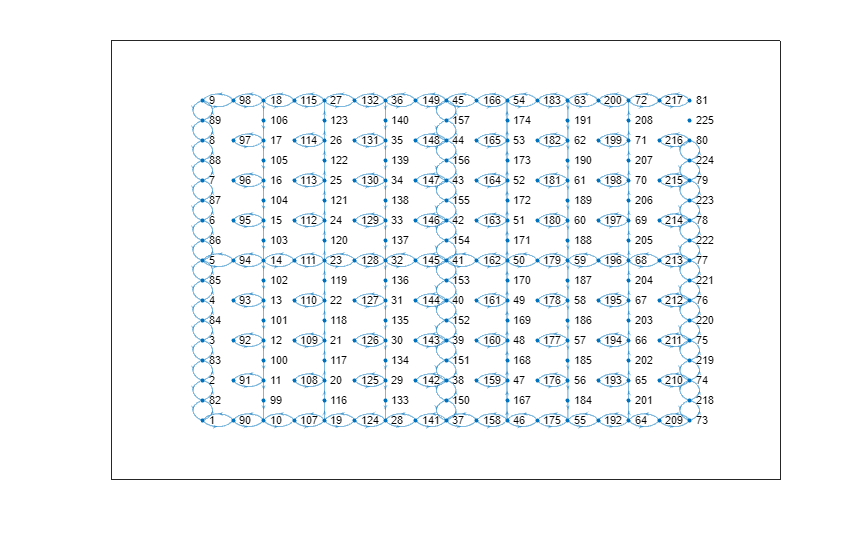

% Setting up the "new" grid which includes the "new" midpoint nodes
f2c4b = figure('Visible','off');
[Q2cGLTN4, ~, Q2cGLTN4MainNodeNames, Q2cGLTN4NewNodeNames, Q2cGLTN4Midpoints, Q2cGLTN4XData, Q2cGLTN4YData] = ...
    ManhattanSquareGridWithMidpoints(N,L,Q2cGLTN4);

Loops = 1; % this cycles through each column
NewNodeIndex = (N-1); % New nodes i.e. 101 to 280
XAlt = 1; % Alternating rows

YAlt = 1; % Alternating columns

% Skipping out the middle row
Rows = 2:(N-1);
Rows(round(end/2)) = [];

for i=1:length(Q2cGLTN4Midpoints)
    % Skipping out the middle column
    if (rem(N,2) == 0 && Q2cGLTN4Midpoints(i) == Q2cGLTN4Midpoints(round(end/2)))
        NewNodeIndex = NewNodeIndex + (N);
    elseif (rem(N,2) ~= 0 && Q2cGLTN4Midpoints(i) == Q2cGLTN4Midpoints(round(end/2)))
        NewNodeIndex = NewNodeIndex + (N-1);
        Loops = Loops + 1;
    % "New" node columns
    elseif (rem(Q2cGLTN4Midpoints(i),0.1) ~= 0)
        % Iterating through th rows - missing out the "outer" and middle rows
        for k = Rows
            if XAlt == 1
                % Deleting left and right bits of columns horizontally
                Q2cGLTN4 = Q2cGLTN4.rmedge(Q2cGLTN4MainNodeNames((Loops-1)*N+k),Q2cGLTN4NewNodeNames(NewNodeIndex+k));
                Q2cGLTN4 = Q2cGLTN4.rmedge(Q2cGLTN4NewNodeNames(NewNodeIndex+k),Q2cGLTN4MainNodeNames((Loops-1)*N+k));
                % Making sure to alternate
                XAlt = 2;
            elseif XAlt == 2
                % Deleting left and right bits of columns horizontally
                Q2cGLTN4 = Q2cGLTN4.rmedge(Q2cGLTN4NewNodeNames(NewNodeIndex+k),Q2cGLTN4MainNodeNames((Loops-1)*N+k));
                Q2cGLTN4 = Q2cGLTN4.rmedge(Q2cGLTN4MainNodeNames((Loops-1)*N+k),Q2cGLTN4NewNodeNames(NewNodeIndex+k));
                % Making sure to alternate
                XAlt = 1;
            end
        end
        % Adding the number of nodes that have been added by the
        % previous loop
        NewNodeIndex = NewNodeIndex + N;
    % "Old" node columns - missing out the "outer" columns
    elseif (Q2cGLTN4Midpoints(i)> Q2cGLTN4Midpoints(1) && Q2cGLTN4Midpoints(i) < Q2cGLTN4Midpoints(end-1))
        if YAlt == 1
            % Deleting top and bottom bits of columns vertically
            Q2cGLTN4 = Q2cGLTN4.rmedge(Q2cGLTN4MainNodeNames(Loops*N+1),Q2cGLTN4NewNodeNames(NewNodeIndex+1));
            Q2cGLTN4 = Q2cGLTN4.rmedge(Q2cGLTN4NewNodeNames(NewNodeIndex+(N-1)),Q2cGLTN4MainNodeNames(Loops*N+N));
            for k = 2:(N-1)
                % Deleting central bits of columns vertically
                Q2cGLTN4 = Q2cGLTN4.rmedge(Q2cGLTN4MainNodeNames(Loops*N+k),Q2cGLTN4NewNodeNames(NewNodeIndex+k));
                Q2cGLTN4 = Q2cGLTN4.rmedge(Q2cGLTN4NewNodeNames(NewNodeIndex+k-1),Q2cGLTN4MainNodeNames(Loops*N+k));
            end
            % Making sure to alternate
            YAlt = 2;
        elseif YAlt == 2
            % Deleting top and bottom bits of columns vertically
            Q2cGLTN4 = Q2cGLTN4.rmedge(Q2cGLTN4NewNodeNames(NewNodeIndex+1),Q2cGLTN4MainNodeNames(Loops*N+1));
            Q2cGLTN4 = Q2cGLTN4.rmedge(Q2cGLTN4MainNodeNames(Loops*N+N),Q2cGLTN4NewNodeNames(NewNodeIndex+(N-1)));
            for k = 2:(N-1)
                % Deleting central bits of columns vertically
                Q2cGLTN4 = Q2cGLTN4.rmedge(Q2cGLTN4NewNodeNames(NewNodeIndex+k),Q2cGLTN4MainNodeNames(Loops*N+k));
                Q2cGLTN4 = Q2cGLTN4.rmedge(Q2cGLTN4MainNodeNames(Loops*N+k),Q2cGLTN4NewNodeNames(NewNodeIndex+k-1));
            end
            % Making sure to alternate
            YAlt = 1;
        end
        % Column index
        Loops = Loops + 1;
        % Adding the number of nodes that have been added by the
        % previous loop
        NewNodeIndex = NewNodeIndex + (N-1);
    end
end
% Plotting updated graph
f2c4c = figure;
Q2hLTN4 = plot(Q2cGLTN4,'NodeLabel',Q2cGLTN4.Nodes.Name);

% Specifying figure size
set(gcf,'units','inches','position',[0,0,16,10])

% Specifying node coordinates
hold on;
Q2hLTN4.XData = Q2cGLTN4XData;
Q2hLTN4.YData = Q2cGLTN4YData;
hold off;
% Verifying required connectivity -> should be 1
sum(conncomp(Q2cGLTN4,'Type','strong'))/(length(Q2cGLTN4XData))
% Disconnecting the final "new" node in the top right corner of the plot as
% a sanity check
Q2cGLTN4 = Q2cGLTN4.rmedge(Q2cGLTN4NewNodeNames(end),Q2cGLTN4MainNodeNames(end));
Q2cGLTN4 = Q2cGLTN4.rmedge(Q2cGLTN4MainNodeNames(end),Q2cGLTN4NewNodeNames(end));
Q2cGLTN4 = Q2cGLTN4.rmedge(Q2cGLTN4NewNodeNames(end),Q2cGLTN4MainNodeNames(end-1));
Q2cGLTN4 = Q2cGLTN4.rmedge(Q2cGLTN4MainNodeNames(end-1),Q2cGLTN4NewNodeNames(end));

% Now all nodes will have varying values due to their independent
% connectivity
sum(conncomp(Q2cGLTN4,'Type','strong'))/(length(Q2cGLTN4XData))
% Plot showing the disconnected node
f2c4d = figure;
Q2hLTN4 = plot(Q2cGLTN4,'NodeLabel',Q2cGLTN4.Nodes.Name);
set(gcf,'units','inches','position',[0,0,16,10])
hold on;
Q2hLTN4.XData = Q2cGLTN4XData;
Q2hLTN4.YData = Q2cGLTN4YData;
hold off;

**(d) Let us suppose that all travellers take the shortest path from their residence to their respective destination (although noting that depending how many links you have deleted — that shortest path may not be unique). Also, for simplicity, you may assume that each street generates exactly the same demand to each of the four corners of the network. Describe, develop, and demonstrate Matlab code which computes the traffic flow on each street for your proposed LTN design. How do flows compare with the setting where no LTN interventions are made? Discuss briefly possible trade-offs in your design: e.g., close off fewer streets, and maybe improve the capacity of others?**

A key point to note here is that due to the destination being randomised between the four corners, each time the code is run the traffic flow on the network changes. This is the main limitation of how this code has been implemented.

- Traffic flow using the desired LTN Design 3 shows a couple of interesting trends. The first, is that the outer two-way streets seem to carry most of the traffic, especially the left hand side outer nodes. This is what is desired from this network with the outer edges carrying most of the traffic flow much like a ring road would. 

- However, something interesting that is commonly spotted when the LTN is implemented is the increase in frequencies on the two-way open sides of blocked-off streets. These streets have some of the highest traffic flows and the reason assumed is that the large traffic flow on the neighbouring one-way street could cause this. However, all nodes have the same amount of generation and so it is not fully clear why this occurs.

- Compared to not using an LTN, traffic appears to not utilise most links particularly frequently. There are however still a couple of links with extremely high flows espcially close to the destinations, in similar places to those seen when the LTN is implemented (especially the left hand side), with others spread out within the network randomly. 

- Some trade-offs do appear with the use of blocked-off streets seen as they are only appropriate in some parts of the network, particularly not in the centre. However, overall they do have a traffic calming effect.

- The increase in capacity of the outer streets is also seen as an opportunity to reduce congestion throughout the whole network, especially close to the destinations. This would be much like a motorway ring road e.g. the M25.

- It could therefore be assumed that the implementation of an LTN, if done correctly, would have minimal impact on traffic flow and avoid extra congested for the most part. However this is very dependent on generation and destination nodes of journeys.

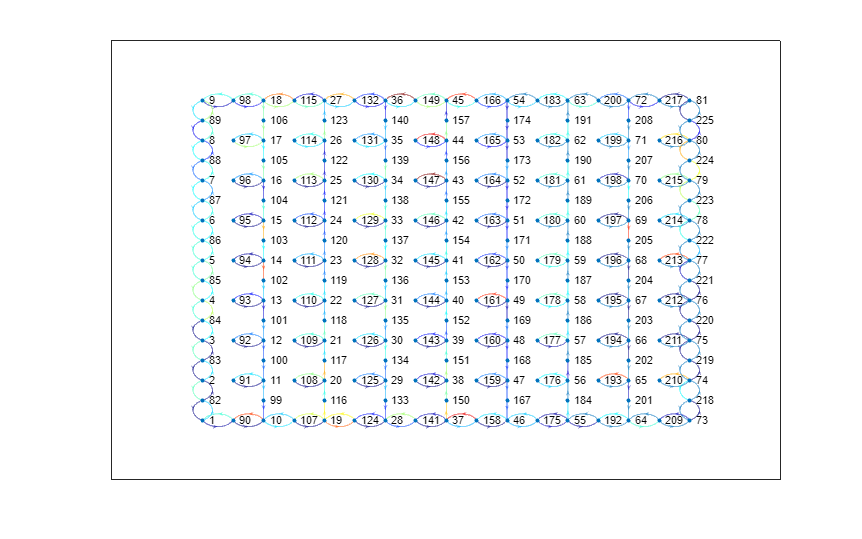


% Adding the nodes back into the graph

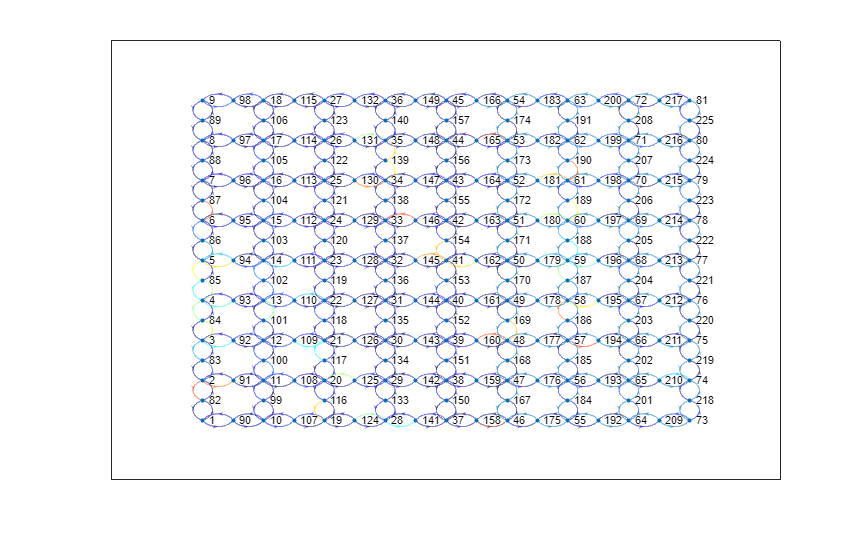


Q2cGLTN3 = Q2cGLTN3.addedge(Q2cGLTN3NewNodeNames(end),Q2cGLTN3MainNodeNames(end),0.1);
Q2cGLTN3 = Q2cGLTN3.addedge(Q2cGLTN3MainNodeNames(end),Q2cGLTN3NewNodeNames(end),0.1);
Q2cGLTN3 = Q2cGLTN3.addedge(Q2cGLTN3NewNodeNames(end),Q2cGLTN3MainNodeNames(end-1),0.1);
Q2cGLTN3 = Q2cGLTN3.addedge(Q2cGLTN3MainNodeNames(end-1),Q2cGLTN3NewNodeNames(end),0.1);

% Creating the figure of the "basic" design
f2d1 = figure('Visible','off');
[Q2dG, ~] = ManhattanSquareGrid(N,L);


% Creating the figure of the LTN design 3 - Maintaining outside loop + one way + blocking off and 
% specifying figure size
f2dLTN = figure;

Q2hLTN3 = plot(Q2cGLTN3,'NodeLabel',Q2cGLTN3.Nodes.Name);
set(gcf,'units','inches','position',[0,0,16,10]);

% Specifying node coordinates
hold on;
Q2hLTN3.XData = Q2cGLTN3XData;
Q2hLTN3.YData = Q2cGLTN3YData;
hold off;


f2dNoLTN = figure;

% Creating the graph for the basic design with midpoints and Specifying figure size
set(gcf,'units','inches','position',[0,0,16,10])
[Q2dGWithMidpoints, Q2dhWithMidpoints, Q2dWithMidpointsMainNodeNames ,Q2dWithMidpointsNewNodeNames,...
    Q2dWithMidpointsMidpoints,...
    Q2dWithMidpointsXData, Q2dWithMidpointsYData] = ManhattanSquareGridWithMidpoints(N,L,Q2dG);

% Setting the names of the destination nodes
DestinationNodes = ["1" , string(N), string(N^2-N+1), string(N^2)];

% Setting the names of the ORIGIN of the trips nodes
OriginNodes = Q2cGLTN3NewNodeNames;

% Setting the number of nodes
TotalNodes = length(Q2cGLTN3MainNodeNames) + length(Q2cGLTN3NewNodeNames);

% Setting up the cell arrays to store the path node indices, length of shortest path and
% indices of edges
LTNpaths = cell(TotalNodes,1);
LTNds = cell(TotalNodes,1);
LTNedgepaths = cell(TotalNodes,1);

NoLTNpaths = cell(TotalNodes,1);
NoLTNds = cell(TotalNodes,1);
NoLTNedgepaths = cell(TotalNodes,1);

% Iterating through all the origin nodes
for i=1:length(OriginNodes)
    % Randomly generating the destination
    Destination = randi([1 4]);
    %Saving the required paths and path lengths tp the relevant arrays
    [LTNpaths{i},LTNds{i},LTNedgepaths{i}] = shortestpath(Q2cGLTN3,OriginNodes(i),DestinationNodes(Destination));
    [NoLTNpaths{i},NoLTNds{i},NoLTNedgepaths{i}] = shortestpath(Q2dGWithMidpoints,OriginNodes(i),...
        DestinationNodes(Destination));
end

% Putting all edges used into a 1D array for frequency calculation
NoLTNtotaluniqueedges = [];
LTNtotaluniqueedges = [];
for i = 1:TotalNodes
    % Only saves unique paths
    if isempty(unique(LTNedgepaths{i})) == 0
        LTNtotaluniqueedges = [LTNtotaluniqueedges unique(LTNedgepaths{i})];
    end
    if isempty(unique(NoLTNedgepaths{i})) == 0
        NoLTNtotaluniqueedges = [NoLTNtotaluniqueedges unique(NoLTNedgepaths{i})];
    end
end

% Calculating frequency of usage for each edge
LTNedgefreq = histcounts(LTNtotaluniqueedges, unique(LTNtotaluniqueedges));
NoLTNedgefreq = histcounts(NoLTNtotaluniqueedges, unique(NoLTNtotaluniqueedges));

% Plotting the edge frequency on a colourmap for the LTN design

hold on;

% Setting up colourmap
cmap = jet(256);

colormap(cmap);
clim([min(LTNedgefreq), max(LTNedgefreq)]);

% Normalising edge frequencies
normedgefreq = normalize(LTNedgefreq,"range");

for i = 1:length(LTNedgefreq)
        %Specifying the colours of each edge
        colorIndex = round(normedgefreq(i)*255)+1;
        %Applying the colours to the relevant edge
        highlight(Q2hLTN3, 'Edges',i, 'EdgeColor', cmap(colorIndex,:))
end

hold off;


% Plotting the edge frequency on a colourmap for the no LTN (basic with midpoints) design
hold on;

% Setting up colourmap
cmap = jet(256);

colormap(cmap);
clim([min(NoLTNedgefreq), max(NoLTNedgefreq)]);
% Normalising edge frequencies
normedgefreq = normalize(NoLTNedgefreq,"range");

for i = 1:length(NoLTNedgefreq)
        %Specifying the colours of each edge
        colorIndex = round(normedgefreq(i)*255)+1;
        %Applying the colours to the relevant edge
        highlight(Q2dhWithMidpoints, 'Edges',i, 'EdgeColor', cmap(colorIndex,:))
end

hold off;